# This is the Live Editor for Upper Kuparuk River Basin Data

Saving daily data instead of hourly

%%%%%%%%
% Reading Upper Kuparuk River Basin data
%%%%%%%%
clear all;
close all;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
colors = [179,0,0
227,74,51
252,141,89
253,204,138
254,240,217]./255;



% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
LL = {'Location','northwest','northeast','southwest','southeast'};



%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;

catchmentA = 1.42e14;%142 km^2 --> mm^2
hour1 = 3600; %seconds 
m3    = 1e9; %mm^3 
txtname = 'UK_thaw_synthesized_data_daily.txt';
m15_d = 27842; %cell number '2003-05-29 10:00'
workdir   = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/';
workdirERRA = '/Users/cansu/Documents/GitHub//Permafrost_ERRA/datERRA/UK_thawingdepth_daily_2';
workdir_s = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data/resource_map_doi_10_18739_A29P2W70H/data';
workdir_m = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/metereological data/';
workdir_d = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/discharge data';
filename_d = 'UpperKuparuk_Historical_Discharge_1993_2018_2018jul17.csv';
filename_m_uk = 'uk1994_2018m_simple.csv';
filename_m_wh = 'wh1996_2010m_simple.csv';
filename_m_ib = 'ib1986_2018m_simple.csv';
writetables = true;


## Discharge

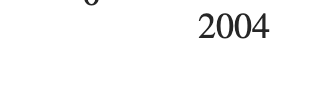

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties


cd(workdir_d)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Station", "Date_Time", "Discharge"];
opts.VariableTypes = ["categorical", "datetime", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Station", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Date_Time", "InputFormat", "yyyy-MM-dd HH:mm");

% Import the data
M_ = readtable(filename_d, opts);

%MANUEL: Some dates MAY not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(M_.Date_Time));
missingdate_index = find(missingdate);
if length(missingdate_index)>1
    for i = 1:length(missingdate_index)
        j = missingdate_index(i);                         %index of the missing value in M_
        dtt = M_.Date_Time(j-1)-M_.Date_Time(j-2);  %time step from the previous times
        M_.Date_Time(j) = M_.Date_Time(j-1)+dtt;    %fill in the missing days
        %TEST: if there is a date in the following point, does it match
        %our dt stepping algorithm?
        if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
            if M_.Date_Time(j) + dtt ~= M_.Date_Time(i+1)
                error('STOP: missing data algorithm failed')
            end
        end
        dttold = dtt;
        if dttold ~= dtt
            error('dtt changed')                %This is not an issue, but I did not test this algorithm for when dttold ~= dtt
        end
    end
end


[trash_ index_trash] = unique(M_.Date_Time,'rows');               %take the date data
M_trash = M_(index_trash,:);
missingdate = isnan(decyear(M_trash.Date_Time));
missingdate_index = find(missingdate);
M_trash(missingdate_index,:) = [];     %if data is still missing, remove row
M = M_trash;
M.Discharge(ismember(M.Discharge,7777)) = NaN;
M.Discharge(ismember(M.Discharge,6999)) = NaN;
t_ = M.Date_Time;
t_cont = t_(m15_d):minutes(15):t_(end); 
index_time_o = find(ismember(t_,t_cont)); %%% index of the original data
index_time_s = find(ismember(t_cont,t_)); %%% index of the continuous data

%export discharge
Q_ = M.Discharge(index_time_o);
Q_cont = nan(size(t_cont));
Q_cont(index_time_s) = Q_; 

%convert time to dateyears
t_cont_num = decyear(t_cont);

%plot it
figQ_plot(t_cont_num,Q_cont,workdir,1)

## Precipitation, Air temperature

cd(workdir_m)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 19);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTimeAST", "MAirTemperaturedegC", "MAirTemperaturedegC1", "MAirTemperaturedegC2", "MAirTemperaturedegC3", "MRelativeHumidity", "MRelativeHumidity1", "MRelativeHumidity2", "MRelativeHumidity3", "MWindSpeedms", "MWindSpeedms1", "MWindSpeedms2", "MWindSpeedms3", "MWindDirectiondegrees", "Rainfallmm", "StationPressuremb", "SnowDepthcm", "VarName18", "VarName19"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["VarName18", "VarName19"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName18", "VarName19"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "DateTimeAST", "InputFormat", "MM/dd/yyyy HH:mm");

% Import the data
Mp_ = readtable(filename_m_uk, opts);

%MANUEL: Some dates are actually not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(Mp_.DateTimeAST));
missingdate_index = find(missingdate);
for i = 1:length(missingdate_index)
    j = missingdate_index(i);                         %index of the missing value in Mp_
    dtt = Mp_.DateTimeAST(j-1)-Mp_.DateTimeAST(j-2);  %time step from the previous times
    Mp_.DateTimeAST(j) = Mp_.DateTimeAST(j-1)+dtt;    %fill in the missing days
    %TEST: if there is a date in the following point, does it match
    %our dt stepping algorithm?
    if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
        if Mp_.DateTimeAST(j) + dtt ~= Mp_.DateTimeAST(i+1)
                error('STOP: missing data algorithm failed')
        end
    end
    dttold = dtt;
    if dttold ~= dtt
        error('dtt changed')
    end
end


[trash_ index_trash] = unique(Mp_.DateTimeAST,'rows');               %take the date data
Mp_trash = Mp_(index_trash,:);
Mp = rmmissing(Mp_trash);

%remove bad data
Mp.Rainfallmm(ismember(Mp.Rainfallmm,7777)) = NaN;
Mp.Rainfallmm(ismember(Mp.Rainfallmm,6999)) = NaN;
Mp.MAirTemperaturedegC(ismember(Mp.MAirTemperaturedegC,7777)) = NaN;
Mp.MAirTemperaturedegC(ismember(Mp.MAirTemperaturedegC,6999)) = NaN;
Mp.MRelativeHumidity(ismember(Mp.MRelativeHumidity,7777)) = NaN;
Mp.MRelativeHumidity(ismember(Mp.MRelativeHumidity,6999)) = NaN;
Mp.SnowDepthcm(ismember(Mp.SnowDepthcm,7777)) = NaN;
Mp.SnowDepthcm(ismember(Mp.SnowDepthcm,6999)) = NaN;


tp_     = Mp.DateTimeAST;
tp_cont = tp_(1):minutes(60):tp_(end)

tp_cont = 1×219144 datetime array
Columns 1 through 1424

   01-Jan-1994 01:00:00   01-Jan-1994 02:00:00   01-Jan-1994 03:00:00   01-Jan-1994 04:00:00   01-Jan-1994 05:00:00   01-Jan-1994 06:00:00   01-Jan-1994 07:00:00   01-Jan-1994 08:00:00   01-Jan-1994 09:00:00   01-Jan-1994 10:00:00   01-Jan-1994 11:00:00   01-Jan-1994 12:00:00   01-Jan-1994 13:00:00   01-Jan-1994 14:00:00   01-Jan-1994 15:00:00   01-Jan-1994 16:00:00   01-Jan-1994 17:00:00   01-Jan-1994 18:00:00   01-Jan-1994 19:00:00   01-Jan-1994 20:00:00   01-Jan-1994 21:00:00   01-Jan-1994 22:00:00   01-Jan-1994 23:00:00   02-Jan-1994 00:00:00   02-Jan-1994 01:00:00   02-Jan-1994 02:00:00   02-Jan-1994 03:00:00   02-Jan-1994 04:00:00   02-Jan-1994 05:00:00   02-Jan-1994 06:00:00   02-Jan-1994 07:00:00   02-Jan-1994 08:00:00   02-Jan-1994 09:00:00   02-Jan-1994 10:00:00   02-Jan-1994 11:00:00   02-Jan-1994 12:00:00   02-Jan-1994 13:00:00   02-Jan-1994 14:00:00   02-Jan-1994 15:00:00   02-Jan-1994 16:00:00   02-Jan-1994 17:00:0

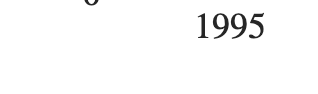

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties


index_timep_o = find(ismember(tp_,tp_cont)); %%% index of the original data
index_timep_s = find(ismember(tp_cont,tp_)); %%% index of the continuous data

%export discharge
P_ = Mp.Rainfallmm(index_timep_o);
P_cont = nan(size(tp_cont));
P_cont(index_timep_s) = P_; 

%export air temperature
AT_ = Mp.MAirTemperaturedegC(index_timep_o);
AT_cont = nan(size(tp_cont));
AT_cont(index_timep_s) = AT_;

%export Relative Humidity
RH_ = Mp.MRelativeHumidity(index_timep_o);
RH_cont = nan(size(tp_cont));
RH_cont(index_timep_s) = RH_;

%export SnowDepth
SD_ = Mp.SnowDepthcm(index_timep_o);
SD_cont = nan(size(tp_cont));
SD_cont(index_timep_s) = SD_;

%convert time to dateyears
tp_cont_num = decyear(tp_cont);


figP_plot(tp_,P_,workdir,1)

ans =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties


figP_plot(tp_cont_num,P_cont,workdir,1)

Test: to see if the P_ and P_cont match up

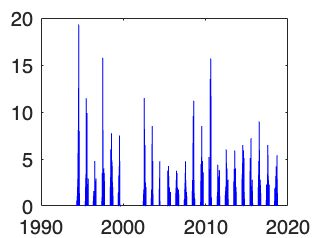

figure
plot(decyear(tp_),P_,'-r')
hold on
plot(tp_cont_num,P_cont,'-b')

## Make the same data size

Notice that precipitation is the sum of the rainfall where logged time is the final discharge count. This means that the averaging I will do for discharge is averaged for the hour before the timestamp. 

shortt = [t_(m15_d):minutes(60):t_(end)]';
shortQ = nan(size(shortt));
short4 = 1:4:length(Q_cont)-4+1;
shortQ(1:length(short4)) = arrayfun(@(i) nanmean(Q_cont(i:i+4-1)),short4)'; %average the result for each hour
index_Q_match_P_1 =  find(ismember(tp_cont,shortt(1)));
index_Q_match_P_end =  find(ismember(tp_cont,shortt(end)));
shortP_cont_match_Q = [P_cont(index_Q_match_P_1:index_Q_match_P_end)]';
shortAT_cont_match_Q = [AT_cont(index_Q_match_P_1:index_Q_match_P_end)]';
shortRH_cont_match_Q = [RH_cont(index_Q_match_P_1:index_Q_match_P_end)]';
shortSD_cont_match_Q = [SD_cont(index_Q_match_P_1:index_Q_match_P_end)]';


## We have data on Thaw Depth 

We have data of thaw depth with time and I have modeled for the regions that did not have the best data by looking up when ground temperature at a region lower down reaches above 0C. I introduce this bias in each year, so it might be a big mistake but lets go with it now. To update this, look at UK_soil_data_compiler. 

My next bias is I do not have data from 2011-2017, so I modeled it from the data that I do have. This builds on the previous assumption.

The issue here is that the data is on a daily basis, where as our data compiler is on an hourly basis so lets extend this data

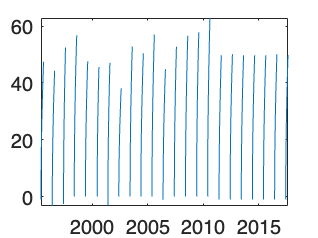

workdir_s = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data';
cd(workdir_s)
load("ThawModel_t_temp_extended.mat")
figure
 plot(t_temperature_extended,ThawThickness_extended)

 %since the time component doesn't quite match, I need to shift the data. 
 index_t_temperature1 = find(dateshift(t_temperature_extended, 'start','day') == min(dateshift(shortt, 'start', 'day')));
 index_t_temperatureend = find(dateshift(t_temperature_extended, 'start','day') == max(dateshift(shortt, 'start', 'day')));
 
 %extend the thawthickness to have same data for each hour of the day and
 %define the corresponding time
 ThawThicknessLong = repelem(ThawThickness_extended(index_t_temperature1:index_t_temperatureend), 24);
 time_thaw = t_temperature_extended(index_t_temperature1):hours(1):(t_temperature_extended(index_t_temperatureend)+days(1));
 
 %now again, fit the time to that of shortt
 index_t_extended_1 = find(time_thaw == min(shortt));
 index_t_extended_end = find(time_thaw == max(shortt));

 ThawThickness_fit = ThawThicknessLong(index_t_extended_1:index_t_extended_end);
 time_thaw_fit = time_thaw(index_t_extended_1:index_t_extended_end);
 

 

## Save files to txt

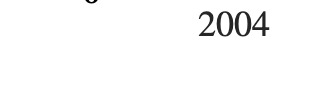

ans =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6000 6.2500]
       Units: 'inches'

  Show all properties


%First make a table
short_t_cont_num = decyear(shortt);
years = year(shortt);
months = month(shortt);
RH = shortRH_cont_match_Q;
airtemp = shortAT_cont_match_Q;
dewpoint = nan(size(years)); %---------
snowdepth = shortSD_cont_match_Q; %--------
groundwater = nan(size(years)); %--------
P = shortP_cont_match_Q;
Q = shortQ*hour1*m3/catchmentA; %<-- convert to m^3/s mm/hr
ThawDepth = ThawThickness_fit';
figtQP_plot_UK_wiMatlab(short_t_cont_num,Q,P,workdir,1)

Daily averages of the data to evaluate with R, but the challenge here is that the response is between 24-30 hours so while you smooth over the daily fluctuations, you lose information on the true intensity.

% %do daily averages of data
% % Define the number of hours in a week
% hours_per_day = 24;
% % Reshape the data into a matrix with one week per column
% num_days = floor(length(airtemp)/hours_per_day);
% time_matrix = reshape(short_t_cont_num(1:num_days*hours_per_day), hours_per_day, num_days);
% months_matrix = reshape(months(1:num_days*hours_per_day), hours_per_day, num_days);
% airtemp_matrix = reshape(airtemp(1:num_days*hours_per_day), hours_per_day, num_days);
% precip_matrix = reshape(P(1:num_days*hours_per_day), hours_per_day, num_days);
% discharge_matrix = reshape(Q(1:num_days*hours_per_day), hours_per_day, num_days);
% SD_matrix = reshape(snowdepth(1:num_days*hours_per_day), hours_per_day, num_days);
% 
% % Calculate the mean of each column to get the weekly averages
% time_da = nanmean(time_matrix, 1);
% months_da = floor(nanmean(months_matrix,1));
% airtemp_da = nanmean(airtemp_matrix, 1);
% precip_da = nansum(precip_matrix, 1).*24; %%precipitation per day
% Q_da = nansum(discharge_matrix, 1).*24; %discharge per day
% SD_da = nanmean(SD_matrix);
% year_time = floor(time_da);
% 
% 

% temp = airtemp_da;
% months = months_da;
% 
% time = time_da;
% 
% cs_T = cumsum(temp);
% DDT = zeros(size(temp));
% 
% for ll = 2:numel(temp)
%     if months(ll) == 1
%         DDT(ll) = 0;
%         continue
%     end
%     if temp(ll) > 0
%        DDT(ll) = DDT(ll-1) + temp(ll);
%     else
%         DDT(ll) = DDT(ll-1) + 0;
%     end
% end
% figure
% plot(time, 2.5*sqrt(DDT),'.k','MarkerSize',25)
% hold on
% DepthAL = load('/Users/cansu/Documents/GitHub//Permafrost_ERRA/datERRA/UK_years/DepthAL_temperature.mat');
% plot(DepthAL.t_,DepthAL.depthAL_trim,'or')
% Z = [2.5*sqrt(DDT) 0];
% 
% dZ = Z(2:end)-Z(1:end-1);
% 
% %set axis
% xlabel('Time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
% ylabel('Thaw Thickness',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
%     title('Thaw Thickness until September, using daily Temperature',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,axh])
%     
% % legend("TillJune","June2July","July2August","GreaterAugust",FS{[1,3]},TX{[1,2]});
% legend("Model","Data",FS{[1,3]},TX{[1,2]},LL{[1,3]});
% 
% 
% %Save files to txt
% %First make a table
% shortt = time';
% years = floor(time)';
% months = months';
% airtemp = temp';
% P = precip_da';
% Q = Q_da'; %<-- mm/day
% ThawDepth = Z(1:end-1)';
% dZ = 0.3.*10.*dZ'; %<-- convert dZ to amount of water (assume 30% water)and cm to mm
% 
% Mtxt = table(shortt,years,months,...
%     airtemp,P,Q,ThawDepth,dZ);
% if writetables ==1
%     cd(workdirERRA)
%     writetable(Mtxt,txtname,'WriteRowNames',true,'Delimiter',',');
%  end
% 
% 




shortt = [t_(m15_d):minutes(60):t_(end)];

temp = shortAT_cont_match_Q;
months = month(shortt);

time = short_t_cont_num;

cs_T = cumsum(temp);
DDT = zeros(size(temp));

for ll = 2:numel(temp)
    if months(ll) == 1
        DDT(ll) = 0;
        continue
    end
    if months(ll) >9
        DDT(ll) = NaN;
        continue
    end
    if temp(ll) > 0
       DDT(ll) = DDT(ll-1) + temp(ll);
    else
        DDT(ll) = DDT(ll-1) + 0;
    end
end
Z = [.5.*sqrt(DDT); 0];
dZ = Z(2:end)-Z(1:end-1);

f1= figure

f1 =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


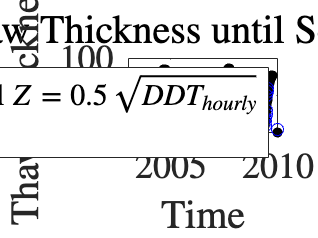

plot(time, Z(1:end-1),'.k','MarkerSize',15)
hold on
DepthAL = load('/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK_years/DepthAL_temperature.mat');
plot(DepthAL.t_,DepthAL.depthAL_trim,'ob')

%set axis
xlabel('Time',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('Thaw Thickness',TX{:},FS{[1,4]},UN{[1,3]});
title('Thaw Thickness until September',TX{:},FS{[1,4]},UN{[1,3]})
    
% legend("TillJune","June2July","July2August","GreaterAugust",FS{[1,3]},TX{[1,2]});
legend("Model $Z = 0.5\sqrt{DDT_{hourly}}$ ","Data",FS{[1,3]},TX{[1,2]},LL{[1,3]});

set(gca,'XLim',[2003,2010],TL{:},FS{[1,4]});



  cd('/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK_thawingdepth_daily_2/figures');
  % set printing options
  str       = {'Thaw_Thickness' };
  format    = '-dpng';
  resl      = '-r400';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');




%Save files to txt
%First make a table
shortt = time;
years = floor(time);
months = months';
airtemp = temp;
P = shortP_cont_match_Q;
Q = shortQ*hour1*m3/catchmentA; %<-- mm/day
ThawDepth = Z(1:end-1);
% dZ = 10.*dZ; %<-- convert dZ to amount of water (assume 30% water)and cm to mm
dw10 = 0.1.*10.*dZ;
dw30 = .3.*10.*dZ;

Mtxt = table(shortt,years,months,...
    airtemp,P,Q,ThawDepth,dZ,dw10,dw30);
if writetables ==1
    cd(workdirERRA)
    writetable(Mtxt,'UK_thaw_synthesized_data.txt','WriteRowNames',true,'Delimiter',',');
 end
